# Modeling uncertain systems with the Ulft class

The Ulft class is the central class for modeling uncertain and nonlinear systems. Objects of this class are passed to the iqcAnalysis function in order to assess robustness properties of the uncertain and nonlinear system. After this script, you will understand what an LFT is, how it is represented with the `Ulft` class, and how to create and combine `Ulft` objects.

## Very brief theoretical background

A Ulft class expresses what are called *linear fractional transformations (LFTs) *of an uncertain and nonlinear system. In this context, LFTs are an interconnection of a certain, linear, "nominal" system M, and a possibly nonlinear, uncertain, "troublesome" operator Delta. This interconnection is a mapping between a "disturbance" input signal $d$ and an output signal $e$ which is expressed by the following equations and block diagram.


$$\qquad \quad \matrix{ \phi & = & \Delta(\theta) \cr
     \theta & = & M_{11} \phi + M_{12} d \cr
     e & = & M_{21} \phi + M_{22} d}$$


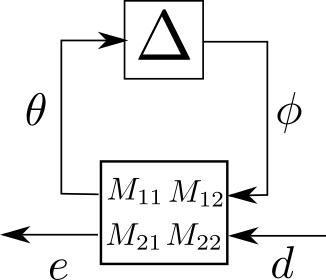

A rational transfer matrix may be represented as an LFT, where the state-evolution operator (either delay for discrete-time or integration for continuous-time) is the Delta block, and M11, M12, M21, and M22 are the `a`, `b`, `c`, and `d` matrices (respectively) for a realization of the transfer function.

gc = rss()
gc_lft = toLft(gc)
gd = drss()
gd_lft = toLft(gd)

Here you can see that the number of states in `gc` and `gd` are reflected in the displayed size of `gc_lft.delta` and `gd_lft.delta`, respectively.  Also, the `a, b, c, d` matrices of the `ss` object and the `Ulft` object match.

gc.a - gc_lft.a{1}

The Delta operator can contain far more than the state-evolution operator though.  It most often has numerous operators which represent additional uncertainties and nonlinearities that are presented in a block diagonal structure:

For example, if the transfer function `gd` is premultiplied by an unknown, time-invariant scalar $\delta \in [0.9, 1.1]$, this (now uncertain) system could be represented with:

del1 = DeltaSlti('del1', size(gd_lft, 2));
gd_uncertain = gd_lft * del1

Now we see that the uncertain transfer function has two deltas: `DelayZ`, and `del1`. 

In this toolbox, even though the state-evolution operators are technically known, we lump them into the Delta block for convenience. Because of this, we use the fields `a, b, c,` and `d` to represent the $M_{11}, \ M_{12}, \ M_{21}, \mbox{ and }  \ M_{22}$ blocks in the equations and block diagram above.

LFTs (we use the class name `Ulft` for *upper *LFTs) are useful to model uncertain and nonlinear systems, because (1) they have a clean separation between the known and the troublesome components of a system and (2) they compose together rather easily.  In other words, you don't need to know how to define the `a, b, c,` and `d` matrices of complicated uncertain systems. This will generally be done with simple operations, such as multiplication and addition.

## How do I make an LFT?

### The `Ulft()` constructor

`Ulft` objects require 5 arguments at a minimum: the `a, b, c,` and `d` matrix, as well as the pertinent `delta` object. For example:

dim_state = size(gc.a, 1);
integrator = DeltaIntegrator(dim_state);
gc_lft2 = Ulft(gc.a, gc.b, gc.c, gc.d, integrator)

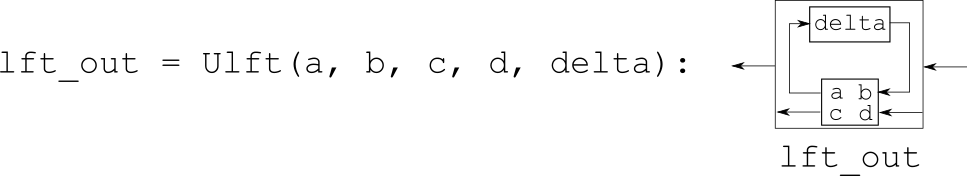

### The `toLft()` helper function

The previous construction requires the `a, b, c,` and `d` matrices, along with the `delta` block (per the block diagram above). The helper function `toLft()` can convert non-Ulft objects into `Ulft` objects.  For example, a matrix can be expressed as an LFT:

lft_eye = toLft(eye(3))

Or a state-space system:

g_ss = rss();
lft_ss = toLft(g_ss)

Or any Delta operator:

del = DeltaSlti('del') % A 1 x 1 static, linear, time-invariant uncertainty within the range [-1, 1]
lft_del = toLft(del) % The equivalent Ulft

State-space systems can also be expressed as `Ulft` objects following the same syntax as `ss` objects.

g_ss_2   =    ss(g_ss.a, g_ss.b, g_ss.c, g_ss.d)
lft_ss_2 = toLft(g_ss.a, g_ss.b, g_ss.c, g_ss.d)

### Converting between Robust Control Toolbox and iqcToolbox -- `rctToLft()` and `lftToRct()` 

You can also convert from `umat `and `uss` objects to `Ulft` objects:

rct_umat = umat(randatom('ureal'));
lft_umat = rctToLft(rct_umat)
rct_uss = rss(2, 1, 1) * rct_umat;
lft_uss = rctToLft(rct_uss)

*NOTE:*

`Delta`* objects obtained from *`rctToLft` *are typically normalized representations of the *`ureal ``or ``ultidyn `*objects. These normalized objects are such that the *`Ulft` *is an equivalent representation of the *`umat` or `uss `*when the uncertainties are evaluated to their normalized values.*

And `Ulft` objects can be converted to `uss` objects:

rct_uss_2 = lftToRct(lft_uss) % Convert the lft back to a uss object

*NOTE:*

*Currently, conversions between the iqcToolbox uncertainties and the Robust Control Toolbox uncertainties are as follows:*

`Robust Control Toolbox  |  iqcToolbox`

`ureal                <-----> DeltaSlti`

`ultidyn              <-----> DeltaDlti`

`umargin               -----> Unsupported`

`ucomplex              -----> Unsupported`

`udyn                 <-----> Any other Delta object (except for DeltaIntegrator and DeltaDelayZ)`

The `udyn` object is a placeholder in the Robust Control Toolbox, and can stand as a representation for `Delta` objects in `iqcToolbox` that cannot be expressed in Robust Control Toolbox.  In some cases, it may be advantageous to convert these placeholders back into `Delta` objects for analysis with `iqcToolbox`.  This can be done by preserving the properties of such placeholders with a mapping.

For example, consider the system:


$$\displaystyle G: \quad \quad \matrix{ 
x(k+1) & = & \left[\matrix{ 0 & 0 \cr 0 & \delta(k)}\right] & x(k)& + & \left[\matrix{\delta(k) \cr 0}\right] & u(k) \cr
y(k) & = & \left[\matrix{1 & 0}\right] & x(k)}$$



$$\mbox{ where } \delta(k) \in [-1/2, 1/2] \mbox{ and } \delta(k+1) - \delta(k) \in [-1/4, 1/4]$$


dim_outin = 1;
bound = 1/2;
rate_bound = 1/4;
del = DeltaSltvRateBnd('del', dim_outin, -bound, bound, -rate_bound, rate_bound);
a = [0, 0;
     0, del];
b = [del; 0];
c = [1, 0];
d = 0;
timestep = -1;
g_lft = toLft(a, b, c, d, timestep)

One might want to manipulate this object in Robust Control Toolbox, and then convert the manipulated system back into a `Ulft` object. While Robust Control Toolbox has no means of expressing time-varying, rate-bounded uncertainties (and must therefore represent such uncertainty as a `udyn` object), the previously defined `del` can be preserved in a mapping, and reinserted with that mapping when converting back to `Ulft` objects.

[g_rct, delta_map] = lftToRct(g_lft); % The rct object with the property preserving mapping
g_rct
g_rct_sqrd = g_rct * g_rct % A new uncertain system made with routines from Robust Control Toolbox
g_lft_sqrd = rctToLft(g_rct_sqrd, delta_map) % The "new" uncertain system converted back to a Ulft

This ability to convert objects between `iqcToolbox` and Robust Control Toolbox allows users to leverage the manipulation/generation capabilities of Robust Control Toolbox, while still retaining the analysis capabilities of `iqcToolbox` for all the same uncertainties amenable under the latter toolbox.

### Generating Random LFTs -- `Ulft.random()`

The convenience method `Ulft.random()` allows us to generate a random LFT.  Though they are typically not robustly stable, every dynamic LFT (i.e., with either a `DeltaIntegrator` or `DeltaDelayZ` block) is nominally stable.

lft_rand = Ulft.random()

You can specify constraints that the randomly generated LFT must satisfy.  The constraints include:

-  the number of Deltas, 

- the required types of Deltas, 

- specific Deltas that must be included, 

- input dimensions, 

- output dimensions, and 

- the `horizon_period` of the LFT (`horizon_period` is described in a latter section).  

For example, if we want a LFT with 2 input channels, 3 output channels, 3 Delta blocks (one of which can be anything, another must be a random `DeltaSlti` object, and the last must be a predefined `del)`, we could do the following:

del = DeltaBounded('del'); % Create a 1 x 1 bounded Delta with l2-induced norm <= 1
lft_rand_2 = Ulft.random('num_deltas',3, 'req_deltas',{'DeltaSlti',del}, 'dim_out',3, 'dim_in',2)

### Composing LFTs from other LFTs 

`Ulft()`, `toLft()`, and `rctToLft() `create LFTs. These LFTs can then be composed together to generate more LFTs.  For example, if you wanted to create an uncertain matrix:


$$X = \left[\matrix{p & qr \cr 0 & 3 - p}\right] = \left[\matrix{0 & 0 \cr 0 & 3}\right] + \left[\matrix{p & 0 \cr 0 & -p}\right] + \left[\matrix{0 & qr \cr 0 & 0}\right], \ \mbox{ where } 
\ \ \matrix{p,q \in [-0.5, 0.5]  \  \mbox{ are time-varying} \cr
r \in [4, 7] \ \mbox{is time-invariant}}$$


dim_outin = 1;
p = DeltaSltv('p', dim_outin, -.5, .5); % Create uncertainty p
q = DeltaSltv('q', dim_outin, -.5, .5); % Create uncertainty q
r = DeltaSlti('r', dim_outin, 4, 7); % Create uncertainty r
mat1 = [0, 0; 
        0, 3];
mat2 = [p, 0;
        0, -p];
mat3 = [0, q * r;
        0,     0];
X = mat1 + mat2 + mat3

Or:

X2 = [p, q * r;
      0, 3 - p]

This uncertain matrix could then be used to define, for example, an uncertain matrix in a state-space system. Recall that a state-space system can be expressed as an LFT:

g_ss = drss(2, 2, 2); % A state-space system
g_lft = toLft(g_ss.a, g_ss.b, g_ss.c, g_ss.d, g_ss.Ts) % A Ulft object of the same system

Suppose then that `b` matrix of this state-space system is actually the uncertain matrix `X`.  This can be expressed with the following:

g_unc = toLft(g_ss.a, X, g_ss.c, g_ss.d, g_ss.Ts) % An uncertain state-space system

And this uncertain `Ulft` could be pre-multiplied with another uncertainty:

del = DeltaPassive('del', size(g_unc, 1));
g_unc_del = g_unc * del

`Ulft` objects can be multiplied, added, subtracted, inverted (if invertible), horizontally concatenated, and vertically concatenated. These operations enable the creation of a single `Ulft` from complicated block-diagrams of many smaller `Ulft` objects.

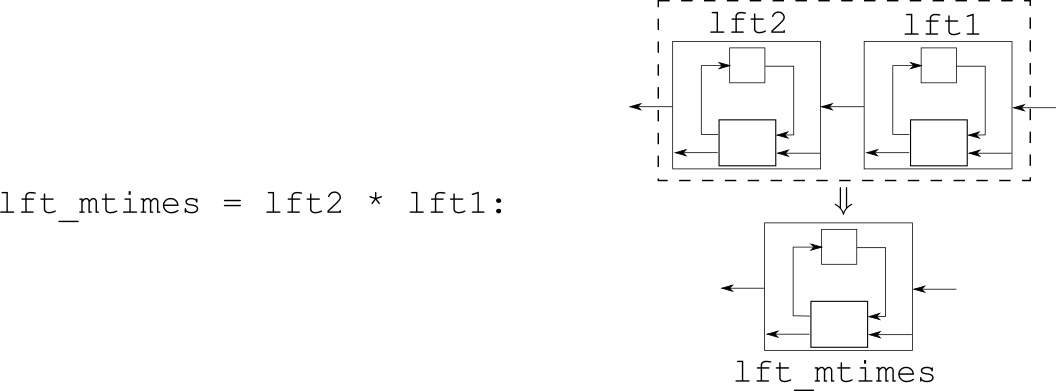

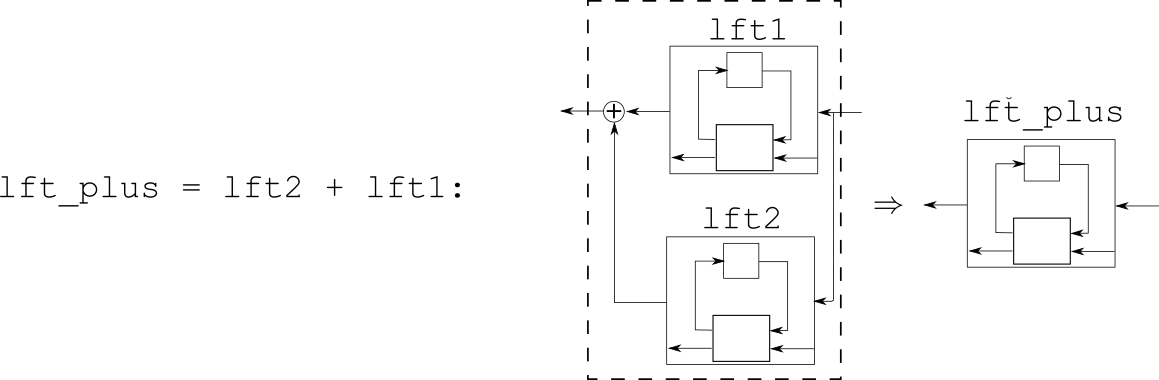

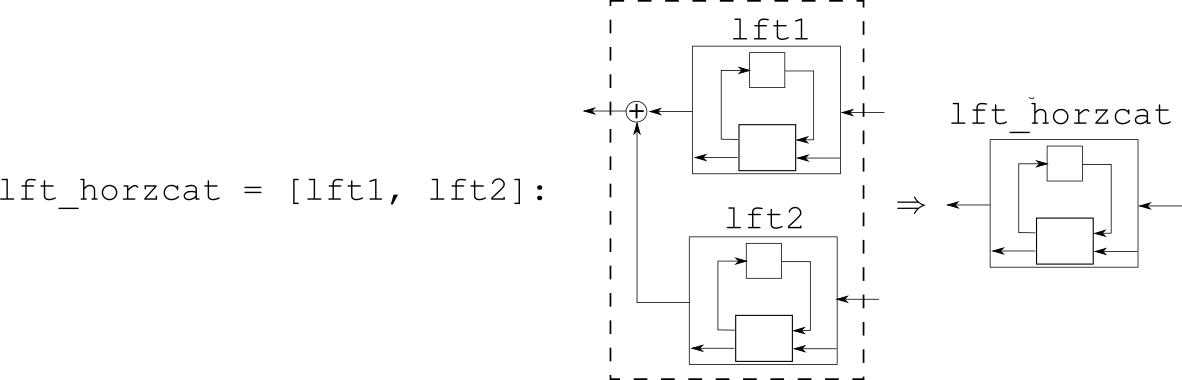

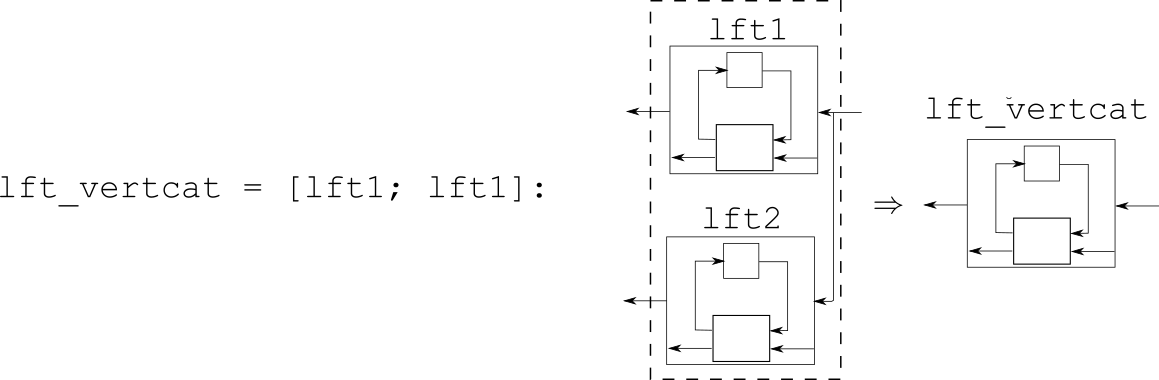

Another important operation for combining `Ulft` objects is defined by the `interconnect` method:

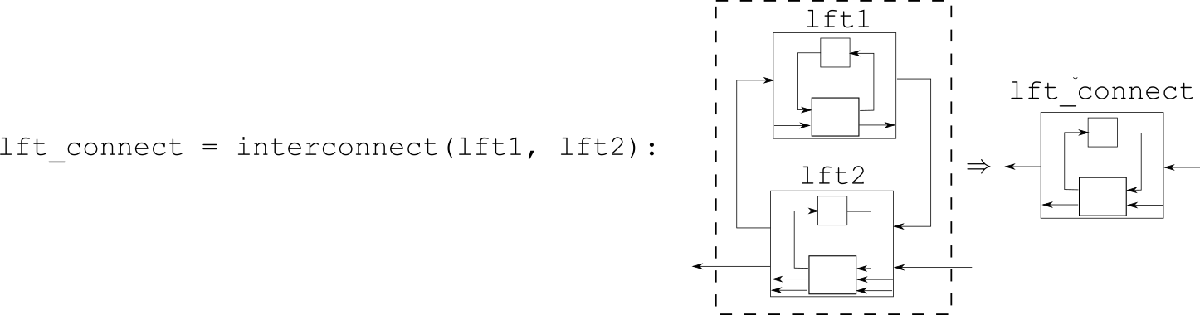

## Additional properties of `Ulft` objects

Till now, we've only discussed the `a`, `b`, `c`, `d`, and `Delta` blocks that express an LFT. However, there are additional `Ulft` properties: `horizon_period`, `disturbance`, and `performance`. Those can be specified in the constructor call:

g_ss = rss();
del = DeltaIntegrator(size(g_ss.a, 1));
horizon_period = [0, 1];
perf = PerformancePassive('passive');
dis = DisturbanceTimeWindow('window');
g_lft = Ulft(g_ss.a, g_ss.b, g_ss.c, g_ss.d, del,...
             'horizon_period', horizon_period,...
             'performance', perf,...
             'disturbance', dis)
         

We'll discuss those last three properties (`horizon_period, performance, disturbance`) in that order.

### What is the `horizon_period property `of a `Ulft` object?

iqcToolbox is capable of analyzing discrete-time time-varying systems. These time-varying systems may be periodic, or finite-horizon, or (more generally) eventually-periodic.  The `horizon_period` of an LFT is used to express its eventually-periodic properties.

#### What is an eventually-periodic LFT?

Given a sequence of matrices $\{X_i\}_{i\in[0, \infty)$, the sequence is `[h, q]`-eventually periodic if $X_{h+j} = X_{h + j + q} \ \mbox{ for all} \ j \in [0, \infty)$. 

In other words, a sequence is `[h, q]`-eventually periodic if, after `h` timesteps, the sequence becomes periodic with a period of `q` timesteps.  A time-varying LFT is `[h, q]`-eventually periodic if each of its sequences of `a`, `b`, `c`, and `d` matrices are `[h, q]`-eventually periodic.

For example, a `[0, 1]`-eventually periodic system is simply time-invariant; it has no horizon `h`, and it has a period of `1`. It's `horizon_period` would be `[0, 1]. `This is the "trivial" `horizon_period`, and the default assumption if unspecified in the `Ulft()` constructor.

A periodic system with period `3` is `[0, 3]`-eventually periodic. It's `horizon_period` is `[0, 3]`.

A finite horizon system whose dynamics are expressed in the first `5` timesteps is `[5, 1]`-eventually periodic. After the first `5` timesteps, the system matrices are set to zeros and become periodic with period `1. `The `horizon_period` of this system is `[5, 1].`

*NOTE:*

*Deltas which are NOT [h, q]-eventually periodic (for example, an arbitrarily time-varying parameter) can still be incorporated in [h, q]-eventually periodic LFTs. Eventual-periodicity expresses the behavior of the a, b, c, d, matrices of the LFT.  There are, however, properties of Deltas, Disturbances, and Performances, which ARE eventually periodic, but those are generally handled in the background (unless users want to exploit that feature).*

*NOTE:*

*Eventual-periodicity is only well-defined for discrete-time systems. iqcToolbox does not currently support time-varying continuous-time systems.*

#### Combining objects with different `horizon_period`

Suppose you wish to combine two different LFTs whose `horizon_period` differ.

lft_rand = Ulft.random('dim_out', 1, 'dim_in', 1, 'horizon_period', [3, 2]);
constant = toLft(1);
lft_rand.horizon_period
constant.horizon_period

This is allowable because a sequence's `horizon_period` is non unique (for example, a `[1, 1]`-eventually periodic system is also `[1, 2]`-eventually periodic, and `[1, 3]`-eventually periodic, and so on), and because two sequences always share a common `horizon_period`. Whenever combining two LFTs, a common `horizon_period` is identified, both objects are re-expressed in that common `horizon_period`, and the two LFTs can be combined. This typically occurs in the background:

lft_combined = lft_rand + constant;
lft_combined.horizon_period

However, there may exist times when you need to make such transformations manually.  This can be done with the function `commonHorizonPeriod `and the method `matchHorizonPeriod`:

new_hp = commonHorizonPeriod([lft_rand.horizon_period;
                              constant.horizon_period])
lft_rand = matchHorizonPeriod(lft_rand, new_hp); 
constant = matchHorizonPeriod(constant, new_hp);
lft_combined_2 = lft_rand + constant;
lft_combined_2.horizon_period

### What is the `performance` property of a `Ulft` object?

Recall that an LFT $(M,\Delta)$ represents a mapping from input disturbance signals $d$ to output signals $e$. For an LFT representing a UAS, $d$ might represent the exogenous wind disturbances acting on the aircraft, while $e$ might be the aircraft's position error. The `performance` property of a `Ulft` object determines the (performance) metric between those two signals.  

The most common performance metric (and default assumption in `iqcToolbox`) is the $\ell_2$-induced norm. Briefly, if an LFT has a robust $\ell_2$-induced norm of $\gamma$, this signifies that


$$||e||_{\ell_2} < \gamma ||d||_{\ell_2}$$


for the output $e$ of the LFT subject to any (finite energy) input $d$.

There are different types of performance metrics though.  One might care to determine if an uncertain system is robustly passive, or just robustly stable.  These different metrics can be considered in IQC analysis.

Consider, for example, the system:


$$\displaystyle G: \quad \quad \matrix{ 
x(k+1) & = & -\delta(k)x(k) + u(k) \cr
y(k) & = & x(k)}$$



$$\mbox{ where } \delta(k) \in [0, 1/2]$$



dim_outin = 1;
del_sltv = DeltaSltv('del', dim_outin, 0, 1/2);
a = del_sltv;
b = 1;
c = 1;
d = 0;
timestep = -1;
g_del = toLft(a, b, c, d, timestep)

The performance of this `Ulft` object is not printed in the display output because it has the default $\ell_2$-induced performance metric. However, one can easily inspect the LFT's performance:

g_del.performance

When the LFT is analyzed, the tightest bound on the robust $\ell_2$-induced performance level will be sought

result = iqcAnalysis(g_del.normalizeLft); % Normalizing to treat asymmetrical uncertainty bounds
result.performance

#### How can I specify the performance metric of an LFT?

Continuing from the previous example, although the system has a robust $\ell_2$-induced performance level of `2`, it is NOT robustly passive.  You can check if the system is robustly passive by specifying a `PerformancePassive` metric in place of the default `PerformanceL2Induced` metric. This can easily be done as follows:

g_del_passive = g_del.addPerformance({PerformancePassive('passive')})

Now we see the performance metric printed because it is a non-default performance.  IQC analysis will now consider *this* performance metric in its routine:

result_passive = iqcAnalysis(g_del_passive.normalizeLft);
result_passive.performance
result_passive.valid

This shows that IQC analysis cannot guarantee the system is robustly passive (strictly input passive, technically speaking).

If instead we only wanted to check if the LFT were robustly stable, we could remove the passive performance metric and add a stability performance metric.

g_del_stable = g_del_passive.removePerformance(1) % Remove first and only performance for the LFT
g_del_stable = g_del_stable.addPerformance({PerformanceStable()}) % Now add PerformanceStable
result_stable = iqcAnalysis(g_del_stable.normalizeLft); 
result_stable.performance
result_stable.valid

A performance metric may also be specified in the construction of a `Ulft` object.

g_del_passive2 = Ulft(g_del.a, g_del.b, g_del.c, g_del.d, g_del.delta,...
                      'performance', PerformancePassive('passive'))

This is an equivalent representation of `g_del_passive`.

*Note:*

*To allow for backend collection and aggregation of performance metrics, users may technically specify a *`Ulft`* which has multiple performances.  However, analysis of such systems is not advised, and will likely produce an error. Unless the *`Ulft`* object has the *`default_l2`* performance, users should be ensure they remove the undesired performance metric before or after adding their desired performance metric.*

### What is the `disturbance` property of a `Ulft` object?

Recall that an LFT $(M,\Delta)$ represents a mapping from input disturbance signals $d$ to output signals $e$. Not only can `iqcToolbox` characterize properties of the uncertainty $\Delta$, but it may also characterize properties of the admissible disturbance signals $d$. This is captured in the `disturbance` property of a `Ulft` object.

The default assumption on disturbance signals $d$ is that they belong to the set of finite energy signals. If using the default $\ell_2$-induced performance metric, IQC analysis searches for an optimal $\gamma$ such that 


$$||e||_{\ell_2} < \gamma ||d||_{\ell_2}, \mbox{ where } e = (M, \Delta)(d)\mbox{ for any admissible } \Delta \mbox{ and any } d \in \ell_2 $$


If we knew (for example) that the input disturbances had constant power spectral density, we could add that characteristic to the disturbance signal, and IQC analysis would then searches for an optimal $\gamma$ such that


$$||e||_{\ell_2} < \gamma ||d||_{\ell_2}, \mbox{ where } e = (M, \Delta)(d)\mbox{ for any admissible } \Delta \mbox{ and any } d \in \ell_2 \mbox{ that has constant power spectral density}$$


This will obviously produce less conservative $\gamma$ values, because additional information on the disturbance is being leveraged in analysis.

#### How can I specify disturbances of an LFT?

Disturbances are displayed, added, and removed much like performance metrics. Recalling the system


$$\displaystyle G: \quad \quad \matrix{ 
x(k+1) & = & -\delta(k)x(k) + u(k) \cr
y(k) & = & x(k)}$$



$$\mbox{ where } \delta(k) \in [0, 1/2]$$


g_del

we note that the default disturbance assumption (that the input is an $\ell_2$ signal) is left unprinted. This can be found easily though:

g_del.disturbance

Adding the constraint that the disturbance must have constant power spectral density is simple:

g_del_white = g_del.addDisturbance({DisturbanceBandedWhite('white')})

Or, if we knew that the disturbance was instead constant for the first 10 timesteps, and then became zero, we could add multiple complementary disturbance constraints:

channels = {[]}; % Empty indicates the disturbance specification pertains to ALL input channels
window = 9; % Time-instance ten (time expressed with zero-indexing)
horizon_period = [10, 1]; % For (10, 1)-eventually periodic properties
% Specify a disturbance set whose signals are constant across the time-window [0, window]:
dis_constant = DisturbanceConstantWindow('constant', channels, 1:window, horizon_period); 
% Specifies a disturbance set whose signals are non-zero only during the time-window [0, window]:
dis_nonzero = DisturbanceTimeWindow('nonzero', channels, 0:window, horizon_period); 
% Modify horizon_period of LFT to be consistent with that of disturbances:
g_del_white = g_del_white.matchHorizonPeriod(horizon_period) 
g_del_multi = g_del_white.removeDisturbance(1) % Remove first and only disturbance characterization
g_del_multi = g_del_multi.addDisturbance({dis_constant, dis_nonzero}) % Add 2 disturbance specs

*Note:*

*Unlike the *`performance`* property, there can be (and in many instances will be) multiple disturbances associated with a single LFT. Having multiple disturbance specifications signifies that the disturbance signal must be an element of the **intersection** of the specified sets (i.e., all the specified constraints must be satisfied), not the **union** of the specified sets (i.e., only one of the specified constraints need be satisfied). A helpful mindset is that the commands *`addDisturbance`* and *`removeDisturbance `*don't add/remove exogeneous disturbances wrt. the LFT, but they add/remove **specifications or constraints** on the already existing disturbance signals of the LFT.*

Similar to the `performance` property, an LFT's disturbances can be specified in the constructor call:

g_del_white2 = Ulft(g_del.a, g_del.b, g_del.c, g_del.d, g_del.delta,...
                    'disturbance', DisturbanceBandedWhite('white'))

## Conclusion

Congrats for finishing this tutorial! By now you should be familiar with the commands for creating `Ulft` objects, manipulating them, specifying and changing their `horizon_period`, and adding/removing their performances and disturbances. 

If you want to understand the more technical design aspects of uncertainties, performances, and disturbances, consider visiting the developer documentation. To get more details on conducting IQC analysis for your generated LFTs, check out the last chapter in the user documentation.